# Examines relationships between cells that are members of pairs

downs = grabFromFilter('Downs - Spikes');
ups = grabFromFilter('Ups - Spikes');

allCells = [ups;downs];

%choose which protocols to look at
priorityOrder_1 = {'Moving_Bar'}; %first field name should be one of these. Priority is in given order
priorityOrder_2 = {'_SP10'}; %child field name should be one of these. Priority is in given order
mustHave_1 = [];
mustHave_2 = {'Extracellular', '_ff'};
cantHave_1 = [];
cantHave_2 = {'Cesium', 'Intracellular', 'Potassium'}; %avoid anything with these tags
rigMandates = []; %no rig mandates
us={};
cellsUsed = {};
PDs = [];
PDDiffs = [];
DSIs = zeros(0, 2);
TCAreas = zeros(0, 2);
NormedAreas = zeros(0, 2);
coordinates = zeros(0, 2);
for i = 1:size(allCells, 1)
    struct_i = allCells{i, 2};
    cname = allCells{i, 1};
    
    if ~isfield(struct_i, 'PairedCells')
        continue
    end
    partnerName = struct_i.PairedCells{1};
    
    if ~ismember(partnerName, allCells(:, 1))
        continue
    end
    
    if ismember(cname, cellsUsed) || ismember(partnerName, cellsUsed)
        continue
    end
    cellsUsed = [cellsUsed, {cname}, {partnerName}];
    
    partnerStruct = allCells{strcmp(partnerName, allCells(:, 1)), 2};
    
    [loc_i, pass_i] = getLoc(struct_i, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    [loc_partner, pass_partner] = getLoc(partnerStruct, priorityOrder_1, mustHave_1, cantHave_1, priorityOrder_2, mustHave_2, cantHave_2, rigMandates);
    
    if pass_i || pass_partner
        continue
    end
    us=[us, {struct_i.cellID}];
    PD_i = mod(loc_i.Analysis_Results.PreferredDirection, 360);
    PD_partner = mod(loc_partner.Analysis_Results.PreferredDirection, 360);

    PDDiffs = [PDDiffs; abs(PD_i - PD_partner)];
    PDs = [PDs; PD_i, PD_partner];
    DSIs = [DSIs; loc_i.Analysis_Results.DSI, loc_partner.Analysis_Results.DSI];
    
    
    %get tuning curve info
    [directions, leaf] = sort(loc_i.Analysis_Results.Orientation);
    tuningCurve = loc_i.Analysis_Results.mean_spikesByOrientation(leaf);
    
    PDResponse = interp1([directions, 360], [tuningCurve, tuningCurve(1)], PD_i);
    tcArea_i = trapz([directions, 360], [tuningCurve, tuningCurve(1)])/360;
    NormedArea_i = trapz([directions, 360], [tuningCurve, tuningCurve(1)]./PDResponse)/360;
    
    clear directions leaf tuningCurve PDResponse
    
    [directions, leaf] = sort(loc_partner.Analysis_Results.Orientation);
    tuningCurve = loc_partner.Analysis_Results.mean_spikesByOrientation(leaf);
    
    PDResponse = interp1([directions, 360], [tuningCurve, tuningCurve(1)], PD_partner);
    tcArea_partner = trapz([directions, 360], [tuningCurve, tuningCurve(1)])/360;
    NormedArea_partner = trapz([directions, 360], [tuningCurve, tuningCurve(1)]./PDResponse)/360;
    
    TCAreas = [TCAreas; tcArea_i, tcArea_partner];
    NormedAreas = [NormedAreas; NormedArea_i, NormedArea_partner];
    
    [xCord, yCord] = pol2cart(struct_i.coordinates.polar(1), struct_i.coordinates.polar(2));
    coordinates = [coordinates; -xCord, yCord];
end

## Figures

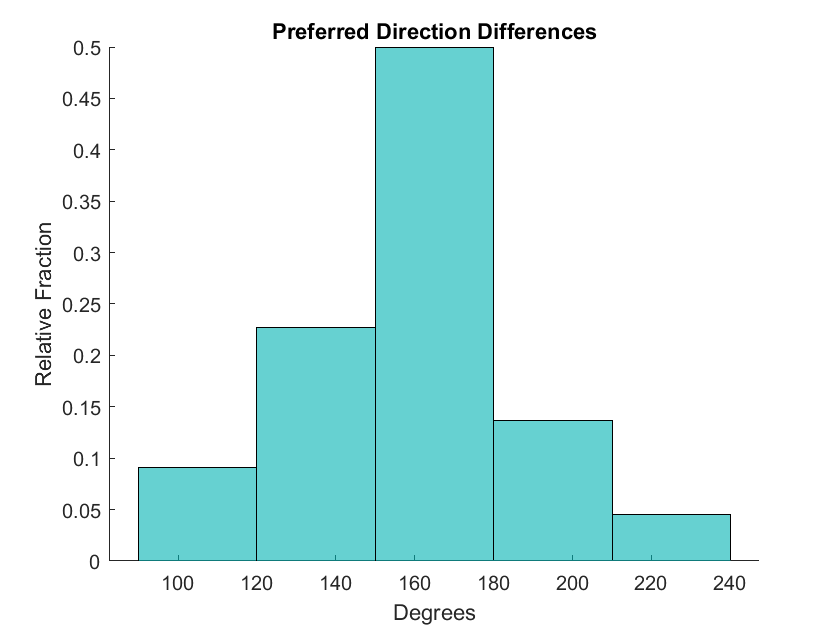


figure
title('Preferred Direction Differences')
hold on
h1 = histogram(PDDiffs, 'Normalization', 'probability');
h1.FaceColor = [0, 0.7, 0.7];
h1.BinWidth = 30;
xlabel('Degrees')
ylabel('Relative Fraction')

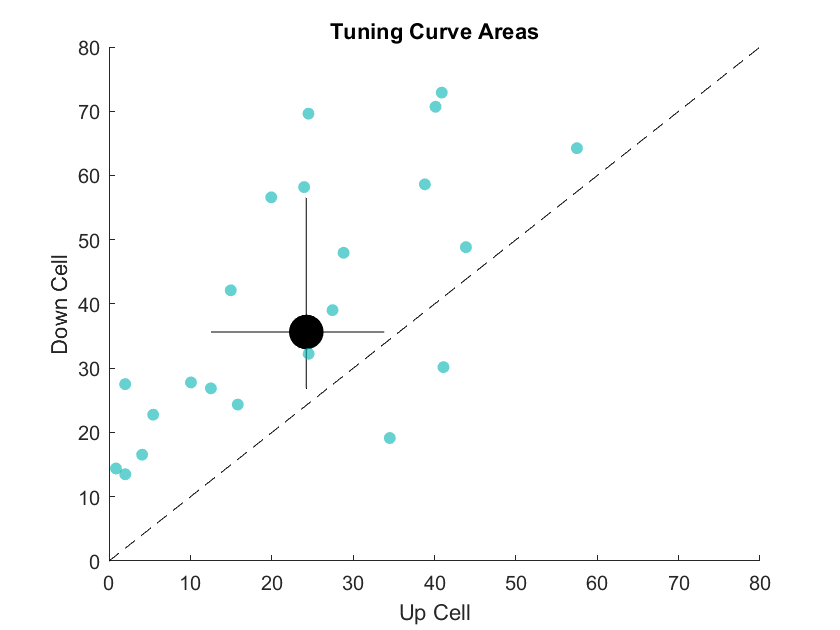


% label cells as Up or Down
upAndDownLabels = zeros(size(PDs));
for i = 1:size(PDs, 1)
    pd_1 = PDs(i, 1);
    pd_2 = PDs(i, 2);
    
    cell_1_90Metric = abs(pd_1 - 90);
    cell_2_90Metric = abs(pd_2 - 90);
    
    if cell_1_90Metric < cell_2_90Metric
        upAndDownLabels(i, :) = [1, 0]; %a 1 indicates its an up cell, a 0 indicates it's a down cell
    else
        upAndDownLabels(i, :) = [0, 1];
    end
end

%see if there's a difference in DSI
upDSIs = zeros(1, size(DSIs, 1));
downDSIs = zeros(1, size(DSIs, 1));
upTCAreas = zeros(1, size(DSIs, 1));
downTCAreas = zeros(1, size(DSIs, 1));
upNormedAreas = zeros(1, size(DSIs, 1));
downNormedAreas = zeros(1, size(DSIs, 1));

for i = 1:size(upAndDownLabels, 1)
    pair = DSIs(i, :);
    
    upCell = logical(upAndDownLabels(i, :));
    downCell = logical((upCell - 1)*-1); %invert 0's and 1's;
    
    upDSIs(i) = DSIs(i, upCell);
    downDSIs(i) = DSIs(i, downCell);
    upTCAreas(i) = TCAreas(i, upCell);
    downTCAreas(i) = TCAreas(i, downCell);
    upNormedAreas(i) = NormedAreas(i, upCell);
    downNormedAreas(i) = NormedAreas(i, downCell);
end

medianX = median(upTCAreas);
medianY = median(downTCAreas);
[~, ~, xER1, xER2] = medianCI95Bootstrap(upTCAreas, 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap(downTCAreas, 10000);



figure
title('Tuning Curve Areas')
hold on
plot([0, 80], [0, 80], '--k')
scatter(medianX, medianY, 300, 'filled', 'k')
plot([-xER1, xER2]+medianX, [medianY, medianY], 'k')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'k')
scatter(upTCAreas, downTCAreas, 'filled','MarkerFaceColor', [0, 0.7, 0.7],  'MarkerFaceAlpha', 0.6)
xlabel('Up Cell')
ylabel('Down Cell')
xlim([0, 80])
ylim([0, 80])

p = signrank(upTCAreas, downTCAreas)

p = 3.3392e-04

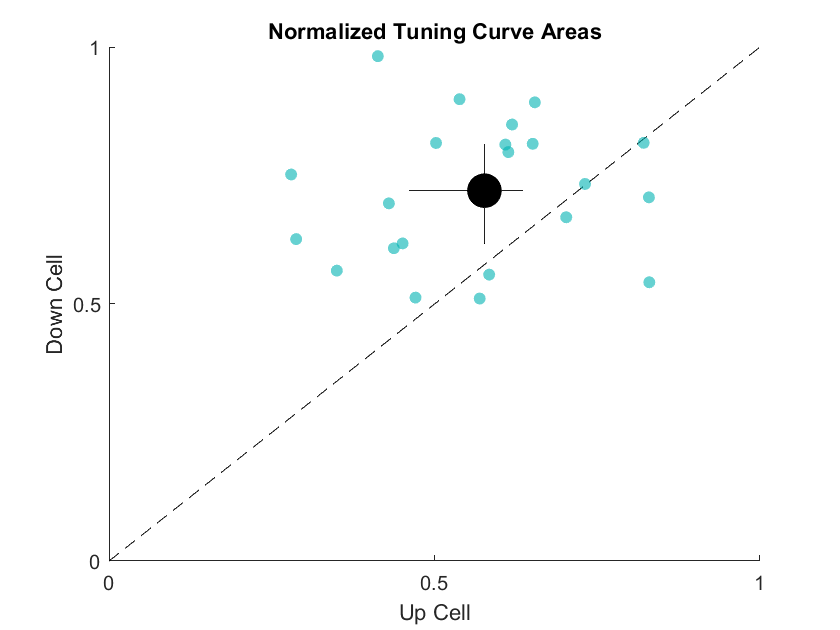

medianX = median(upNormedAreas);
medianY = median(downNormedAreas);
[~, ~, xER1, xER2] = medianCI95Bootstrap(upNormedAreas, 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap(downNormedAreas, 10000);



figure
title('Normalized Tuning Curve Areas')
hold on
plot([0, 1], [0, 1], '--k')
scatter(medianX, medianY, 300, 'filled', 'k')
plot([-xER1, xER2]+medianX, [medianY, medianY], 'k')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'k')
scatter(upNormedAreas, downNormedAreas, 'filled','MarkerFaceColor', [0, 0.7, 0.7],  'MarkerFaceAlpha', 0.6)
xlabel('Up Cell')
ylabel('Down Cell')
xlim([0, 1])
ylim([0, 1])
xticks([0:0.5:1])
yticks([0:0.5:1])


p = signrank(upNormedAreas, downNormedAreas)

p = 0.0045

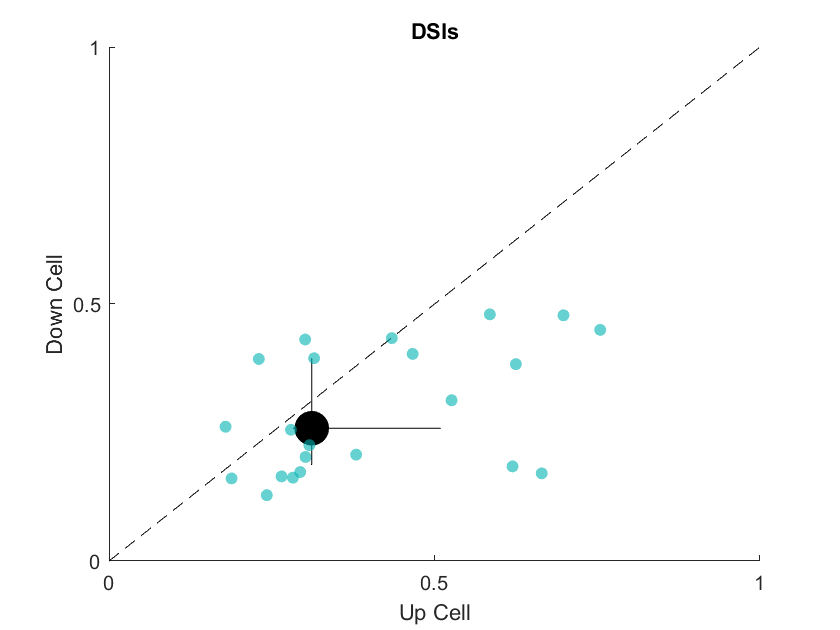



medianX = median(upDSIs);
medianY = median(downDSIs);
[~, ~, xER1, xER2] = medianCI95Bootstrap(upDSIs, 10000);
[~, ~, yER1, yER2] = medianCI95Bootstrap(downDSIs, 10000);



figure
title('DSIs')
hold on
plot([0, 1], [0, 1], '--k')
scatter(medianX, medianY, 300, 'filled', 'k')
plot([-xER1, xER2]+medianX, [medianY, medianY], 'k')
plot([medianX, medianX], [-yER1, yER2] + medianY, 'k')
scatter(upDSIs, downDSIs, 'filled','MarkerFaceColor', [0, 0.7, 0.7],  'MarkerFaceAlpha', 0.6)
xlabel('Up Cell')
ylabel('Down Cell')
xlim([0, 1])
ylim([0, 1])
xticks([0:0.5:1])
yticks([0:0.5:1])

p = signrank(upDSIs, downDSIs)

p = 0.0050

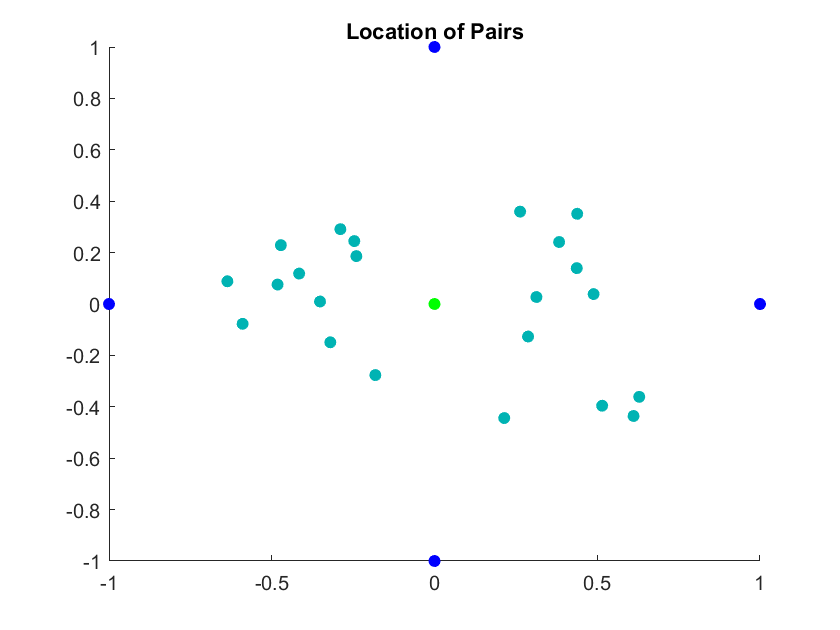


figure
title('Location of Pairs')
hold on
scatter(coordinates(:, 1), coordinates(:, 2), 'filled','MarkerFaceColor',[0, 0.7, 0.7])
scatter(0, 0, 'g', 'filled')
scatter([1 0 -1 0], [0 1 0 -1], 'b', 'filled')